# Example: COVID-2019 data for Hubei, China (22-Jan-2020-18-Mar-2020)

I am taking some data, collected into DATA.mat from John Hopkins university [1]

[1] [https://github.com/CSSEGISandData/COVID-19](https://github.com/CSSEGISandData/COVID-19)

**Important notice:**

The fitting is here more challenging than in Example 1 because the term "Confirmed patient" used in the database does not precise whether they have been quarantined or not. In a previous version of the submision (version <1.5) , the infectious cases were erroneously used instead of the quarantined cases. 

## Initialisation

The parameters are here taken as constant except the death rate and the cure rate.

clearvars;close all;clc;
load('DATA.mat','tableRecovered','tableDeaths','tableConfirmed','time')

indLocation = find(contains(tableRecovered.ProvinceState,'Hubei')==1)

indLocation = 156


Recovered = table2array(tableRecovered(indLocation,5:end));
Deaths = table2array(tableDeaths(indLocation,5:end));
Confirmed = table2array(tableConfirmed(indLocation,5:end));
% If the number of confirmed Confirmed cases is small, it is difficult to know whether
% the quarantine has been rigorously applied or not. In addition, this
% suggests that the number of infectious is much larger than the number of
% confirmed cases
Recovered(Confirmed<=10)=[];
Deaths(Confirmed<=10)=[];
time(Confirmed<=10)= [];
Confirmed(Confirmed<=10)=[];
% time = datetime(2020,02,24):1:datetime(2020,03,17);

Npop= 14e6; % population

## Fitting of the generalized SEIR model to the real data

guess = [0.06,1.2,1/5,1/40,0.1,0.05,0.1,0.02]; % my guess for the fit
E0 = Confirmed(1); % Initial number of exposed cases (we do not know it, so it is set at zero)
I0 = Confirmed(1); % Initial number of infectious cases (we do not know it, so it is the number of quarantined)
Q0 = Confirmed(1);
R0 = Recovered(1);
D0 = Deaths(1);

[alpha1,beta1,gamma1,delta1,Lambda1,Kappa1] = ...
    fit_SEIQRDP(Confirmed-Recovered-Deaths,Recovered,Deaths,Npop,E0,I0,time,guess);


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          9     6.33964e+11                      8.31e+13
     1         18     9.30365e+10      0.0474911       1.14e+13      
     2         27     3.61692e+10     0.00747864       1.48e+12      
     3         36     3.61692e+10        0.12856       1.48e+12      
     4         45     3.00004e+10        0.03214        2.8e+11      
     5         54     2.63241e+10      0.0642801       3.04e+11      
     6         63     1.61667e+10      0.0642801       1.18e+11      
     7         72     8.34318e+09        0.12856       6.26e+10      
     8         81     5.02463e+09       0.226523       2.27e+11      
     9         90     1.94056e+09      0.0908731       2.88e+11      
    10         99     1.56428e+09      0.0976888       3.14e+11      
    11        108     1.37293e+09      0.0463939       1.21e+11      
    12        117     1.37293e+0

## Simulate the epidemy outbreak based on the fitted parameters

dt = 0.1; % time step
time1 = datetime(time(1)):dt:datetime(2020,3,25,0,0,0);
N = numel(time1);
t = [0:N-1].*dt;
[S,E,I,Q,R,D,P] = SEIQRDP(alpha1,beta1,gamma1,delta1,Lambda1,Kappa1,Npop,E0,I0,Q0,R0,D0,t);

## Comparison of the fitted and real data

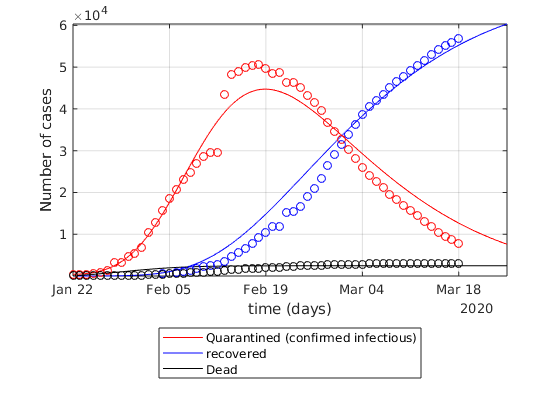

figure
semilogy(time1,Q,'r',time1,R,'b',time1,D,'k');
hold on
semilogy(time,Confirmed-Recovered-Deaths,'ro',time,Recovered,'bo',time,Deaths,'ko');
% ylim([0,1.1*Npop])
ylabel('Number of cases')
xlabel('time (days)')
% leg = {'susceptible','exposed','infectious','quarantined','recovered','Dead','insusceptible'};
leg = {'Quarantined (confirmed infectious)','recovered','Dead'};
legend(leg{:},'location','southoutside')
set(gcf,'color','w')
grid on
axis tight
% ylim([1,8e4])
set(gca,'yscale','lin')